# CurveFitting

This script discusses model building and the interpretation of data and demonstrates linear and nonlinear methods to fit models to data with MATLAB. 

Author: Duncan Carlsmith 

### **Introduction**

Scientific methods provide a means to test and quantify knowledge. This script provides an introduction to the theory of quantitative data-model comparison ([regression](https://en.wikipedia.org/wiki/Regression_analysis)), and to the practice of parameter estimation using a simulation of a ballistic trajectory and a linear polynomial motion model.   MATLAB linear regression with matrix methods and the use of MATLAB regression functions `nlinfit, fitnlm, ` `polyfit,` and `fit `are illustrated. Both `nlinfit` and `fitnlm` can fit linear and nonlinear functions of parameters to data and are recommended. These functions are available for interactive use via the [MATLAB Curve Fitting Toolbox](https://www.mathworks.com/products/curvefitting.html). `polyfit` is a strictly linear quick fitting option available on MATLAB plot menus. The script illustrates how discover the  `polyfit` parameters and their  uncertainties via the command line. `fit `is a general purpose fitting package that includes more sophisticated modeling strategies. 

The use of MATLAB fitting packages is straightforward once you know how, but accessing the fitted parameter values with their uncertainties is, um, obscure. This script is rather a manual in that respect.

### Theory

#### $\chi^2$ and maximum likelihood in curve fitting

Suppose we have `n` measured values $y_i$  corresponding to values $x_i$  with $i=1,...,n$ and we wish to model this data with a  function $y(x,\theta)$ with a vector of $p$ parameters $\theta$. On what basis shall we choose the parameters? One choice is to treat all values $y_i$ on an equal basis and to minimize with respect to the parameters the sum of squared deviations (the sum of the [residuals](https://en.wikipedia.org/wiki/Errors_and_residuals) squared) between the model and the data . Define


$$\chi^2 = \sum_i (y(x_i,\theta)-y_i)^2/\sigma^2$$


where $\sigma$ is an arbitrary scale factor with the dimensions of $y$ introduced to render $\chi^2$ dimensionless. Then find the values $\theta_m$ that make this function a minimum.

That's all well and good if we just want to represent points, perhaps in order to guess interpolated or extrapolated values (often a very risky thing to do). In science, however, our model typically has a theoretical basis. The $y_i$ are observations of some dependent variable like vertical displacement of an object and the $x_i$ are values of an independent variable like horizontal displacement or time. Our simplest model is actually


$$y_i = y(x_i,\theta )+ e_i$$


where $y(x_i,\theta)$ is an idealized data model based in theory,   $e_i$ is a so-called error model describing the contribution from always present uncontrolled random influences, and the $x_i$ values are safely assumed exactly known. We expect each $e_i$ to be different in any given experiment and we expect on average each  $e_i$ to vanish if we have eliminated systematic (non-random) effects or incorporated these into our data model. Often we discover the the $e_i$ are independent and normally distributed with zero mean and variances $\sigma_i^2$. In this case, the [likelihood](https://en.wikipedia.org/wiki/Likelihood_function)  $L$of our set of observations, defined to be the product of the probabilities of each observation in turn, has the expression

$L\propto \prod_i {1\over\sqrt{2\pi\sigma_i^2}}e^{-{(y_i-y(x_i,\theta))^2\over{2\sigma_i^2}}}$.

A standard practice is to use the [maximum likelihood principle](https://en.wikipedia.org/wiki/Likelihood_principle) and derive standard best estimates of the parameters  $\theta$  by maximizing the likelihood of the fixed sample observations $y_i$. The maximum likelihood principle method where applicable results in parameter estimates that are generally the most robust, unbiased, and generally optimal.

 For a  likelihood function of multiple parameters $\theta$, a maximum is indicated if all [partial derivatives](https://en.wikipedia.org/wiki/Partial_derivative)  vanish simultaneously implying  $p$ equations expressible as

${\partial L\over\partial \theta_j}=0$.

Here we have assumed the error model is completely known since a single data sample may not suffice to determine the parameters of an error model. (For example, if the $e_i$ are supposed distributed normally and are  independent, a single $y_i$ cannot determine both the mean and variance of the correponding $e_i$.) When the likelihood is a product of positive definite independent probabilities (when in our general model the values $e_i$ are uncorrelated), maximizing $L$ is equivalent to maximizing its logarithm and hence, for a product of normal distributions, to minimizing the quantity

$\chi^2=\sum_i {(y_i-y(x_i,\theta))^2\over{\sigma_i^2}$.

We see the maximum likelihood principle affords a statistical interpretation of the naive approach. Significantly, each squared residual is weighted in inverse proportion to its variance so points with relatively large uncertainty carry relatively little weight. This incorporation of prior knowledge (of the error model) in our estimation makes intuitive sense. (Incorporation of  prior knowledge of the data model parameters is best accomplished within a different [Baysian](https://en.wikipedia.org/wiki/Bayesian_statistics) framework.)

The system of equations corresponding to a minimum  $\chi^2$


$${\partial\chi^2\over\partial\theta_j}=\Sigma_i{{ (y_i-y(x_i,\theta)) }\over\sigma_i^2}{\partial y(x_i,\theta)\over\partial \theta_j}=0$$


is linear in the parameters $\theta_i$ if $y$ is a linear function of the parameters $\theta$ (a special case  called linear regression) and an analytic solution may be found by matrix algebra. More generally,  a multi-dimensional iterative numerical method must be employed to solve the equations. Starting with some estimate for the location $\theta_m$ of the minimum, the estimate is adjusted in the direction indicated by the sign and magnitude of the derivatives until the magnitude of all derivatives is smaller than some tolerance. Such so-called nonlinear regression is generally accomplished using a computer.

**Goodness of fit and parameter uncertainties**

Given the data and error models and the estimate $\theta_m$ , we can use the data to estimate how close $\theta_m$ is to the true parameter values, bearing in mind that our model may be incorrect and that we have a limited sample. If we fit $n$ data points to a model with $p$ parameters with $n=p$, in the absence of random contributions $e_i$, we could generally find an exact fit to the data with vanishing $\chi^2$. In the presense of random contributions, for $n>p$, with exact fit values for the parameters such that $y_i-y(x_i,\theta)=0$, we expect 


$$\chi^2=\sum_{i=1}^n e_i^2/\sigma_i^2>0$$


i.e. $\chi^2$ should be a sum of normally distributed random variables and itself be a random variable. The probability distribution of  such a sum of random variables is a  noncentral $\chi^2_n$-distribution ( [https://en.wikipedia.org/wiki/Chi-squared_distribution](https://en.wikipedia.org/wiki/Chi-squared_distribution) ) and a central (normal) $\chi_n^2$ distribution in the simplest case of a common variance $\sigma_i^2=\sigma^2$. In this common simplest case, fitting for $p$ parameters  in effect removes fluctuations equivalent to $p$ of the degrees of freedom in the data sample. Consequently  $\chi^2(\theta_m)$ is actually a random variable with values distributed as $\chi^2_{n_{dof}$ with $n_{dof}=n-p$. The mean value of $\chi^2_n$ is $n$ and the variance of  $\chi_n^2$ is $2n$ and for large n  $\chi^2_{n}$ is approximately a normal distribution so  we expect to find $\chi^2(\theta_m)$to be in the range $n_{dof}\pm\sqrt{2n_{dof}}$ roughly 68% of the time ([with 68% confidence](https://en.wikipedia.org/wiki/68%E2%80%9395%E2%80%9399.7_rule)).  Often, we use the data itself to estimate $\sigma^2$ thereby effectively reducing the number of degrees of freedom further by one so use $n_{dof} = n-p-1$.

To quantify the quality of a fit, we calculate $\chi^2/n_{dof}$, the $\chi^2$ per degree of freedom in our sample, and expect to find a value in the range $1\pm\sqrt{2/n_{dof}}$ which is roughly unity for large $n_{dof}$. A value small or large compared to 1 is unlikely and suggests there are too many or too few parameters in the data  model, a poor estimate of $\sigma^2$ has been used, or there is some other failure of the overall scheme.  A value within the "1-sigma" range just indicated constitutes a "[good fit](https://en.wikipedia.org/wiki/Goodness_of_fit)" if we use this approximate 68% probability criterion, however uncertain the results for parameters might be, and does not necessarily imply the data model is correct. It only suggests the overall model is consistent with epectation for the particular sample. Reducing the uncertainties by collecting more data might prove the model inconsistent with collective observations. 

In describing your fit results, provide the value of $\chi^2$ and $n_{dof}$ so readers may determine for themselves as they wish the precise likelihood that the model is consistent with the data, and describe precisely your procedures for making any further statistical inferences.

By numerical sampling of the values of $L$ in the neighborhood of $\theta_m$, or in special cases by analytic means, we can infer the range of deviations $\theta - \theta_m$ corresponding to any likelihood range and specify  multi-dimensional parameter range consistent with the data at any confidence level. This range is not necessarily centered on $\theta_m$ and the confidence level range for one parameter depends on the values of others. Usually, scientists loosely characterize the volume containing all likely parameter values using the maximal range for each parameter variation in turn and choose (most often) to quote a 68%, 90% or 95% confidence level range for that parameter equivalent to $\pm$ one, two , or three standard deviation for a normal distribution.

**Comparing models**

If  $\chi^2_{n_{dof}}$ is outside the expected range for some model, we can sensibly then ask if an adjusted model  might for the same sample result in a $\chi^2$ consistent with the expected value for that model. For example, suppose we find  a naive model $y(t)=y_0+v_0t+(1/2)gt^2$ is not a good fit to measured displacement values $y_i$ a times $t_i$ for a falling object and we use theory or other empirical evidence to include aerodynamic drag in a more complex model with the same or possibly more free parameters such as a drag coefficient. Roughly, a rational basis for favoring a model 1 as opposed to  a model 2 is that $\chi^2_{n_{dof}}$ is lower by  1 or larger for model 1 than $\chi^2/n_{dof}$ for model 2. 

Consider the statement "The quadratic free-fall model fit has $\chi^2/n_{dof}=5$ while a fit to the model including air drag with $\chi^2/n_{dof} =1.1$ is statistically consistent with the data and produces a best fit drag coefficient of $C_D= x.xx\pm0.yy$ ." Note that such a statement does not rule out completely the quadratic free-fall model. One aways might be unlucky in collecting a sample of data subject to random influences. Neither does it claim that the model with drag is the only model that could account for the data. Nor does it prove the air drag model is correct. It could be that the fitted value $C_D$ is wildly inconsistent with direct measurements of the air drag effect or with the validated theory of fluid mechanics and that the effect ascribed to air drag is in reality due to an entirely different source. At best one can only make claims about hypotheses that appear inconsistent with data, not about the uniqueness of any one of the infinite number of models which could be consistent with any data sample. See [all models are wrong](https://en.wikipedia.org/wiki/All_models_are_wrong) and [overfitting](https://en.wikipedia.org/wiki/Overfitting) for further discussion.

#### Bias resulting from an incorrect error model

A maximum likelihood analysis is a test  of the idealized model together with the error model. Suppose we observe an exponentially decaying count rate distribution resulting from radioactive decay of some collection of nuclei, and that $y_i$ represents [Poisson distributed](https://en.wikipedia.org/wiki/Poisson_distribution) counts of decay events observed in a  time window of width $\Delta t$ about some uniform seqence of times $x_i$. Our theoretically motivated data model is $y(t) \propto e^{-t/\tau}$ (or more precisely the integral of this quantity over the time interval) where $\tau$ is a parameter representing the characteristic nuclear decay time. The data model is nonlinear in this parameter. The variances associated with intrinsic fluctuations in counts are  $\sigma_i^2 \simeq  y_i$, i.e. not the same for every data point.   Parameters derived according to the maximum likelihood principle with  variance common to all points  will give equal weight to points with large and small relative uncertainty. The estimated parameter values and their uncertainties will consequently be [biased](https://en.wikipedia.org/wiki/Bias_of_an_estimator). 

#### Estimating variance from fit

Often we have not measured the variance of the distribution of values on any of the $e_i$ and have but one sample of each  $y_i$ and $x_i$. In this case, we might perform a fit assuming normally distributed uncorrelated errors, and then use the data itself to estimate the variance assumed common to all data points in an ad hoc fashion. We assume the fit is essentially perfect, plot all of the residuals between fit and data (should be a normal distribution if all data points have the same variance) and fit that to estimate $\sigma$. It is this techique that MATLAB curve fitting functions generally employ in effect for unweighted fits. We simply give the MATLAB fitting function a model function $y(x,\theta)$ and  the data t $y_i$, and the fitting function process returns  the best estimate parameter values and estimated uncertainties on the parameters based on  single value $\sigma^2$ derived from the residuals distribution itself. 

Take care in using such a simple procedure. Prior to the fit and detailed study, we do not necessarily  know that the values are independent and the variances are the same for each point. Neither do we know if the data model is entirely appropriate. 

A first step is to plot the residuals from the first pass fit. Data points wildly off the mark might need to be culled at the expense of introducing some hypothesis about the origin of such anomalies. 

Suppose we observe an unexpected trend in the residuals in additional to what appears to be normally distributed noise, i.e. systematic variation with the independent variable, runs of high values and runs of low values, and what appears to be random deviations up and down. A next step would be to fit the residuals to a generic model (a polynomial for example) sufficient to account for the trends along with random noise. With the trend removed, we might verify the adjusted residuals are normally distributed by histograming their distribution and fitting that distribution to a normal distribution and performing tests for independence such as a runs test. If these are consistent with the hypothesis of normally distributed independent noise, we can estimate the variance of the noise. We are left then explain the trend through some augmentation of the theoretical model.

Suppose we are using an incomplete model $y(\theta, x)$but a correct error model.  If we estimate the variance of the data from data itself, i.e. from the residuals to the fit without removing any systematic trends, the estimated variance will be larger than the noise variance, and the value of $\chi^2/n_{dof}$will by construction be close to 1. In general, determining $\sigma$ from the data itself renders moot a comparison of models based on $\chi^2/n_{dof}$ alone. The uncertainties on the parameters of the incomplete model will include in an ill-defined sense the systematic error associated with the unexplained trends. If we refit the data to the original data model with the validated noise model using the noise variance found from the data, and include additively in the data model the parametrized empirical model for the trend, the uncertainties on all of the free parameters will reflect  the statistical uncertainty associated with the noise. However, this procedure has introduced the hypothesis that the trend parameters are independent of the original data model parameters.

**Uncertainties in the independent variable**

Beware also that the MATLAB curve fitting tools and the maximum likelihood method as described above presume the $x_i$ are known. If there are important uncertainties in the values of the independent variable, a more complicated method is needed. One ad hoc approach is to use at each point a variance which is the sum of the variances in x and in y and continue to fit for $y(x,\theta)$as if $x$ were perfectly known. If the variances in x and y are common to all data points, derive from normal distributions, and are indepdendent, then unweighted fits can correspondingly be scaled using $\sigma^2=\sigma_x^2+\sigma_y^2$, and interpreted as has been described. When $\sigma_x^2<<\sigma_y^2$, inclusion of variations in the independent variable may be neglected in practice.

#### Linear regression

A linear regression model is one in which the data model  depends linearly on the parameters, i.e. it is a sum of parameters multiplying known functions. Its component functions need not be linear functions of the independent variable. A polynomial with coefficients as parameters is an example of a linear model. Closed form expressions may be found for the maximum likelihood estimated parameters and for their uncertainties. See the Wikipedia articles [Linear regression](https://en.wikipedia.org/wiki/Linear_regression) and [Ordinary least squares](https://en.wikipedia.org/wiki/Ordinary_least_squares).    

Using the notation for parameters in the Wikipedia article, we want to fit observations $y_i,$ (for $i=1,...,n$) with parameters $\beta_j, ~j=0,...,p$ and errors $\epsilon_i$ to the model: 

$y_i = \beta_0 +\beta_1*x_{i,1}+...+\beta_p*x_{i,p}+\epsilon_i$.

The model function on the right-hand-side is linear in the parameters $\beta$. The quantities $x_{i,j}$ are values of arbitrary functions $x_i(t)$ evaluated at independent variable values $t_j$. Let X be the matrix with rows $X_i=(1, x_{i,1}, ..., x_{i,p})$. In matrix form, the model is: 

$y = X\beta+\epsilon$.

The matrix solution in the absence of errors, $\beta = X^{-1}y$ , applies if $X$ is a square invertable matrix. In general, we have more data points than parameters and the mathematical problem is over constrained. The maximum likelihood/least squares estimate solution in the presence of errors (of assumed zero mean) is $\beta = (X'X)^{-1}X'*y$ where $X'$ is the transpose of $X$. The more contraints/data, the better we determine the parameters and the better we can test our assumptions. 

We will not derive this solution here but show in what follows how it is easily implemented in MATLAB for any data set and for any linear combination of functions, be they polynomial terms, harmonic functions, exponential functions, or special functions. Such models commonly appear in physics as first approximations. When one is  interested in estimating parameters such as frequency or time parameters internal to such functions, one requires nonlinear regression. 

### **Practice**

#### A toy model

To study regression in practice with MATLAB, we will use pseudo data representing observations of 1d ballistic motion.  Suppose at $n$ times $t_i$, we measure the vertical position $y_i$  of an object. We use the model function

 
$$y= y_0+v_0 t +(1/2)g t^2+(1/6)jt^3$$
 

to simulate the results for various values of the parameters $y_0$, $v_0$, $g$, and $j$, turning jerk off by setting $j$ = 0. The quadratic term corresponds to uniform gravitational acceleration. The physical origin of the cubic jerk term might be an addtional time dependent electric force for a charged particle, or an effect of wind for a balloon. 

The measured values will deviate from expectation due to random influences in measurement and we will simulate that noise too. We assume the random contributions to each measurement are uncorrelated and normally distributed about means of zero, with a common variance. These assumptions might apply  if we measure all the `y` values with a ruler with the same technique. (One should always test such assumptions.)

We will fit for all three or four parameters and change notation $\theta\rightarrow \beta$ to conform to the Wikipedia and MATLAB notion, i.e. we will fit for $\beta_0= y_0$, $\beta_1 = v_0$, $\beta_1 = g$, and $\beta(2)=j$ permitting all to be positive or negative. (The signs will depend on the chosen direction for positive y, either up or down.) Our model is linear and the functions in the linear model notation above are $x_1 = 1$, $x_2 = t$, $x_3 = t^2/2$ and $x_4=t^3/6$. Let's get to work.

Clear out variables and figures.

clear all; delete(findall(0,'Type','figure'))

Reset random number generator for reproducibility

rng('default')

We set a section break here so you can rerun the following section without resetting the random number generator. You will then get a fresh simulation with each section run.

#### Set simulation parameters

Set default values for simulation including the model parameters initial position, velocity, acceleration of gravity, and jerkfraction, and for the error model std of used in generating pseudodata (MKS units). We introduce a tunable parameter `jerkfraction,` the magnitude of the ratio of the jerk term to of the acceleration term at the maximum time. Jerkfraction=1 means the jerk term is as big as the acceleration term at the max time. 

**Try this**: Feel free to play with any of these parameter values.

n = 200 ;% number of data points. 
tmax = 20;% maximum time
jerkfraction = 5;% fractional jerk effect
e = 200;% standard deviation of measurement errors
y0 = 10;% initial postion
v0 = 40;% initial velocity
g =-10;% acceleration of gravity
jerk = jerkfraction*3*g/tmax;% constant jerk

Set the number of parameters in the data model.

**Try this**: The jerk term in the simulated data can be turned on and off by setting `jerkfraction` to 1 or 0 above. The jerk term in the data model used to fit the simulated data can be turned off by setting `p=3`  or turned on by setting `p=4` below.

p = 3  ;% number of parameters to fit.

Fill a row vector` t` with times (seconds) from 1 s up to` tmax`.

t=[1:n]*tmax/n;

Fill row vector with squares of times (over 2!) and times cubed (over 3!). Note use of  [Element-wise multiplication](https://www.mathworks.com/help/matlab/matlab_prog/matlab-operators-and-special-characters.html).

t2 = t.*t/2;  % equivalent to t.^2/2
t3 = t.^3/6 ; 

Fill a matrix X with columns of ones, times `t`, and values for `t.^2/2`, and for  `t.^3/6` if needed, via [concatenation](https://www.mathworks.com/help/matlab/math/creating-and-concatenating-matrices.html) (using brackets) of the [transpose](https://www.mathworks.com/help/matlab/ref/transpose.html) t'=transpose(t). Note, [ones(n,m)](https://www.mathworks.com/help/matlab/ref/ones.html) generates an n by m matrix with 1 in each element. If we fit to 4 parameters not 3, we need an additional column. This matrix is required for closed form linear regression.

X=[ones(n,1) t' t2'];
if p==4
    X=[ones(n,1) t' t2' t3'];
end

Create a simulated data row vector `y` according to the data model and add errors.  [Randn](https://www.mathworks.com/help/matlab/ref/randn.html)`(1,n)` returns a random sample from a normal (Gaussian) distribution with 0 mean and unit standard deviation. We scale those deviations by a tunable parameter `e`.

y = y0+v0*t+g*t2+jerk*t3+e*randn(1,n);

Fill column vector `err` for plotting values with error bars. Use the standard deviation of the noise as generated. (We are assumig the error model is known.) You might use a value extracted from the data - see below -  in a more realistic scenario in which you do not have an independent measurement of the noise distribution. 

err = e*ones(n,1);

Method to export and read back if ever needed.

% Write the data to a spreadsheet just for fun
% xlswrite('linearRegressionExcel.csv',[t' y' err])
% Open EXCEL to read the csv and save it as .xlxs then 
% you can read it back into a matrix by uncommenting the following line
% myExcelData = xlsread('linearRegressionExcel.xlsx')

Plot data with error bars using [errorbar](https://www.mathworks.com/help/matlab/ref/errorbar.html) command, and mark points with an asterix character. (There are other marker options.) Label the plot.

errorbar(t,y,err','*')
xlabel('Time (s)')
ylabel('Vertical position (m)')

Retain the plot so we can superpose fit results.

hold on 

#### Matrix-based linear regression

Calculate the linear regression fit parameters via matrix manipulations. The function [inv](https://www.mathworks.com/help/matlab/ref/inv.html) returns the inverse of a matrix.

beta=inv(X'*X)*X'*y'

beta =       -388.98
       319.43
      -83.389


FYI: Linear regression parameters may be more simply calculated as` beta=X\(y')`.

Create row vector of predicted positions using fit parameters including the jerk term if we choose to.

yp= beta(1)+beta(2)*t+beta(3)*t2;
if p==4
    yp= beta(1)+beta(2)*t+beta(3)*t2+beta(4)*t3; 
end

Estimate of the variance (assumed common to all points) from data-fit residuals. (See theory of estimating the mean and variance of a normal distribution.)

epsilon = (yp - y)';
s2 = (epsilon'*epsilon)/(n-p);

Compare the corresponding standard deviation value `s2^(1/2)` to the value `e` used in generating pseudo data. The estimate could be quite wrong for a low number of degrees of freedom.

s = sqrt(s2),e

s =        284.54


e =    200


Estimate $\chi^2/n_{dof}$. Since we estimate `e` from the data, the result is guaranteed to be near 1 whether we have the wrong model or not.

chisquarenNormalized = ((n-p)/(n-p-1))*s2/s^2

chisquarenNormalized =        1.0051


Compute the [covariance matrix](https://en.wikipedia.org/wiki/Covariance_matrix) of fit parameters using the closed form solution derived from matrix-based linear regression. 

cov = s2*inv(X'*X)

cov =        3717.3       -741.6       61.646
       -741.6       196.17      -18.311
       61.646      -18.311       1.8219


Standard deviations of parameter values ignoring correlation are derived from the covariance matrix diagonal elements in linear and nonlinear models. The function [diag](https://www.mathworks.com/help/matlab/ref/diag.html) returns the elements along the diagonal of a matrix. The function [sqrt](https://www.mathworks.com/help/matlab/ref/sqrt.html) happily returns the square roots of the elements of a vector or an entire array of arbitrary dimensions. Thanks MATLAB. 

Derive parameter standard errors for the matrix-based linear regression method.

betaerror = sqrt(diag(cov))

betaerror =         60.97
       14.006
       1.3498


Print the results of the fit with standard errors using [fprint](https://www.mathworks.com/help/matlab/ref/fprintf.html). Char(177) is \pm. This demonstration may be useful in writing results to a text file.

% y0Est = [num2str(beta(1)),'+-',num2str(betaerror(1))]% one way to print
fprintf(['y0Est= ','%0.2f ' char(177) ' %0.2f\n'], [beta(1);betaerror(1)])

y0Est= -388.98 ± 60.97


fprintf(['v0Est= ','%0.2f ' char(177) ' %0.2f\n'], [beta(2);betaerror(2)])

v0Est= 319.43 ± 14.01


fprintf(['gEst= ','%0.2f ' char(177) ' %0.2f\n'], [beta(3);betaerror(3)])

gEst= -83.39 ± 1.35


if p==4
    fprintf(['jerkEst= ','%0.2f ' char(177) ' %0.2f\n'], [beta(4);betaerror(4)])
end

Superpose data model using parameters found by the fit atop the data using [plot](https://www.mathworks.com/help/matlab/ref/plot.html) and include a legend.

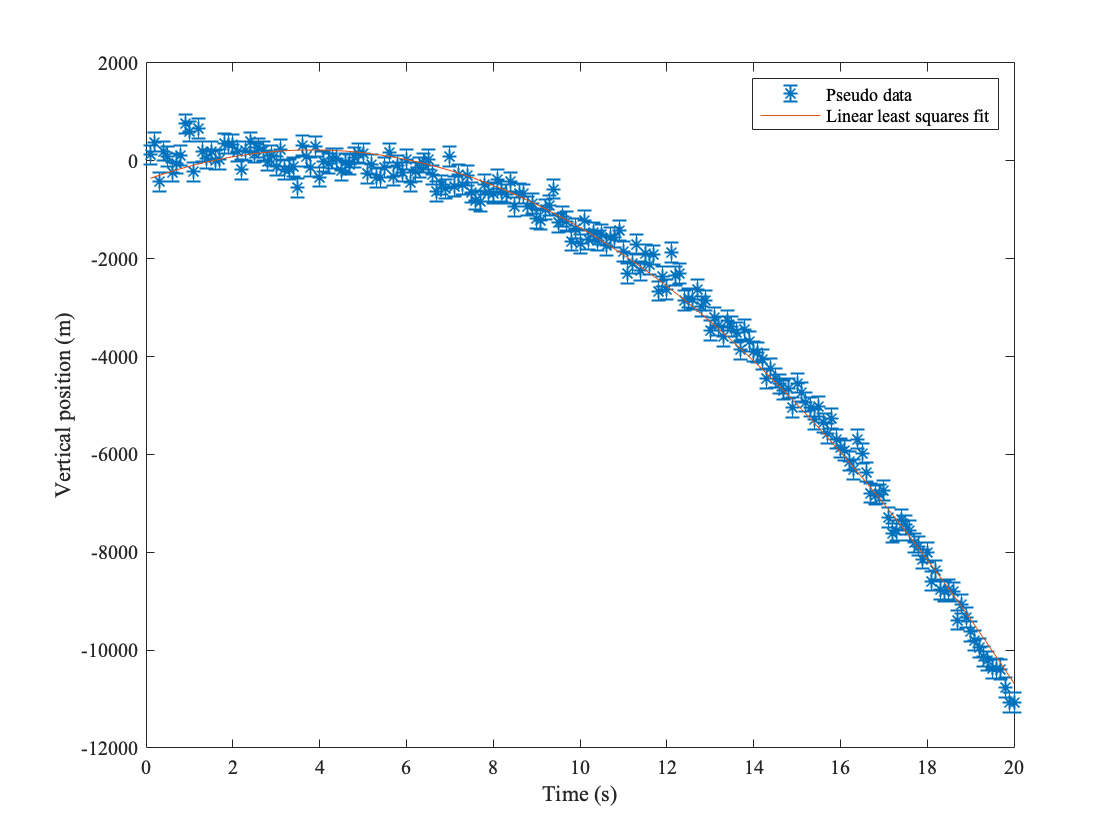

plot(t,yp)
legend('Pseudo data','Linear least squares fit')

Notice the data points are close to the fitted curve, typically within the error bars, but not always. If the data+error model is correct, we expect only 68% of points to be inside of the error bars. We should check that if that number obtains for the fit.

Notice too that the curve appears systematically high in places and systematically low in other places when we fit a model with jerk to data simulated without jerk or a model without jerk to simulated data with jerk. 

**Try this**: You can vary the` jerkfraction` value and the error scaling parameter `e` to see at what fraction a wrong data model is not distinguishable from a correct data model for a given noise level.

Create and plot data-fit residuals column vector. We use the plot default setting to display lines not points to best exhibit point-to-point fluctuations as well as trends.

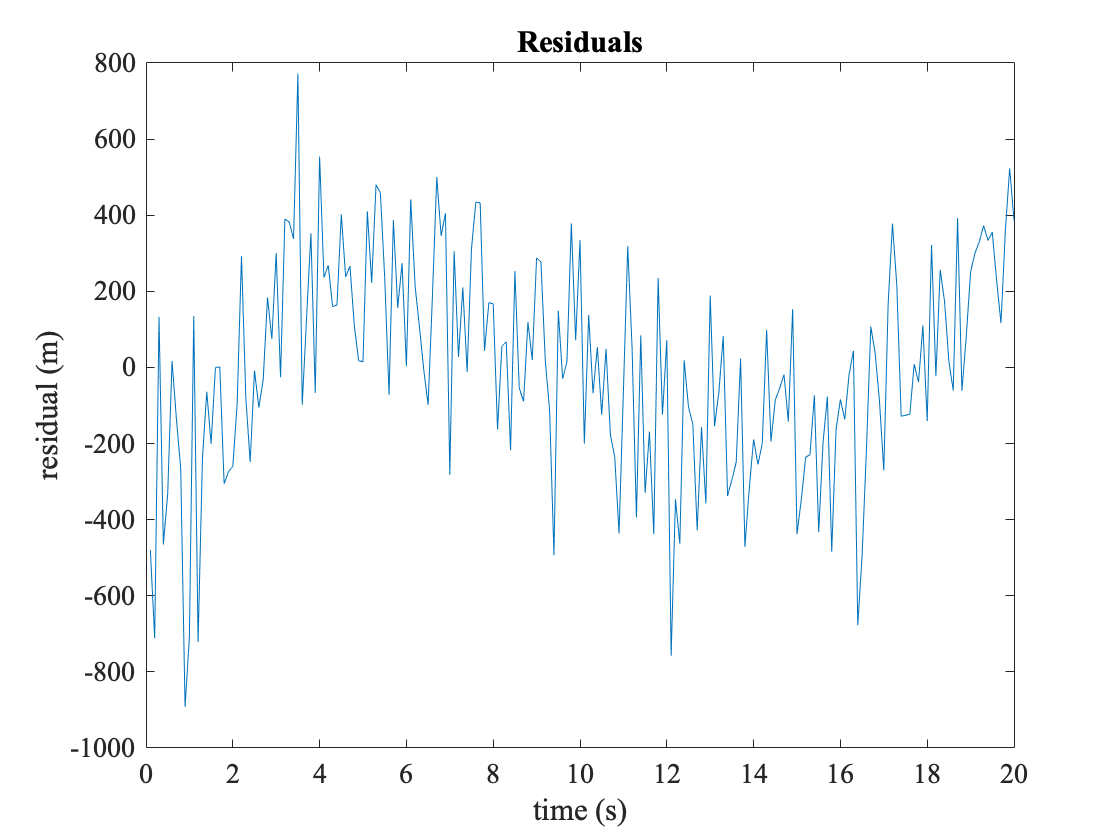

figure
plot(t,epsilon)
title('Residuals')
xlabel('time (s)');ylabel('residual (m)')

Significant trends are more evident in the residuals plot that in the plot of the data itself with fit superposed. The eye is good at picking out trends, and sometimes too good. We observe as well what appears to be normally distributed  noise. We have used an incorrect data model. We can still check the error model as follows. 

**Try this**: At this point, one might want to fit the residuals to a low order polynomial model for the systematic effect, and then fit with [histfit](https://www.mathworks.com/help/stats/histfit.html) a histogram of the residuals of THAT fit to a normal distribution to check that the flucuations observed there are normally distributed about the evident systematic trends and to estimate from the data the variance in the error model.

#### Nonlinear regression with `nlinfit`

Now we will illustrate how to use the nonlinear regression function [nlinfit](https://www.mathworks.com/help/stats/nlinfit.html).

We start by defining an [anonymous](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) data model function we will call `modelfun` that we can pass as an input [function handle](https://www.mathworks.com/help/matlab/function-handles.html) to `nlinfit.` An [anonymous function](https://www.mathworks.com/help/matlab/matlab_prog/creating-a-function-handle.html) is essentially a function one defines on the fly, without the normal rigamarole associated with a function one saves in a file for use by vaious scripts. Our `modelfun` has two arguments, a vector of fitting parameters `b`, and a vector` t` containing the values of the independent variable (time). In general, `nlinfit `will be calling `modelfun` repeatedly with evolving parameter valuess `b` (read beta) as it steps numerically  toward the solution to the $\chi^2$ minimization problem. (Since our model is actually linear, `nlinfit` will actually solve oiur whole problem in one step starting from the starting values for the parameters we also supply.) 

Start by defining a default model function without the jerk term using a symbolic representation employing components of a vector `b` of parameters and a vector `t` of independent variable values. Note the use of  .* in the 3rd (nonlinear) term. This function is going to be supplied vectors b and t via a call of the form modelfun(beta, x) with beta and x vectors containing parameter and independent variable values during iterative solution of the $\chi^2$ minimization problem, and return a vector of predicted values for all of the independent variable values. The use of elementwise multiplcation means t.*t is a vector like b(2)*t. When the scalar b(1) is added, MATLAB will add it elementwise to the vectors in the other terms using its implicit rules for addition. We don't have to write the first term as b(1) times a unit vector. The model function must return a vector of length equal to the length of its second argument `t` from the two input vector arguments `b` and `t`.

modelfun = @(b,t)(b(1)+b(2)*t+b(3)*t.*t/2);
%modelfun = @(b,t)(b(1)+b(2)*t+b(3)*t*t/2);

Redefine the model function including the jerk term if jerk has been enabled in the model. Notice again the elementwise multiplication.

if p==4
    modelfun = @(b,t)(b(1)+b(2)*t+b(3)*t.*t/2+b(4)* t.^3/6);
end

**Tip**: If you inadvertantly omit elementwise multiplication, and have a term like t*t in the model function, MATLAB will create a matrix from that term and, in attempting to add this matrix to a vector result of another term, throw an error. Be careful, as always.

**Try this**: Deliberately break this script by removing the periods from the model function definition to see what error `nlinfit` will throw. A good way to proceed is to copy the model function definition, paste it as the next line of code, and alter the copy. To revert you can then just comment out or delete the offending line of code. An altered and commented out line of code that will break the script has been prepared for you above. If p=3, `nlinfit` should throw an error when trying to use this function.

We have to give `nlinfit` initial estimates for the parameters to start. Provide the actual simulation parameter values as the estimates.

b0 = [y0;v0;g];
if p==4
    b0= [y0;v0;g;0];
end

There are various options for fitting with `nlinfit` (see documentation for nlinfit), so many that `nlinfit` is built to not only accept a variable number of named arguments, but to use a whole structure containing values affecting its operation. These values are set using a function [statset](https://www.mathworks.com/help/stats/statset.html) as the followoing call illustrates.

opts = statset('nlinfit');

We will content ourselves with the default values of parameters controlling the fitting, including the $10^{-8}$ value for the tolerance on locating the minimum value of $\chi^2$. 

Note the following: `nlinfit `can perform weighted fits. We can set the weights to a common value of unity for example. Since we don't need weights for our example,  the following illustrative call with weights is commented out.

%weights = ones(n,1)';
%opts.RobustWgtFun = 'bisquare';
%[beta,R,J,CovB,MSE,ErrorModelInfo] = ...
%  nlinfit(t,y,modelfun,b0, 'Weights', weights);

Now we call `nlinfit` providing it our independent variable values `t`, our observations `y`, the name of the model function `modelfun`, and the initial parameter values  `b0`. It returns and we catch the minimum $\chi^2$ solution parameter values $\beta$, several matrices, and additional information.

[beta,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(t,y,modelfun,b0);

According to the  `nlinfit` documentation, if $f(x,b)$ is the model function of the independent variable $x$ and parameters $b$, and $w$ the weights, the residuals are $r_i = \sqrt(w_i)*(y_i-f(x_i,b)$ and the so-called Jacobian  is  `J` with $J_{ij} = \partial f(x_i,b)/\partial b_j$. For linear regression, $J$ is the matrix $X$ in the notation we have been using. If J, has full column rank meaning  it is invertible,  then the covariance matrix of the parameters is `CovB = inv(J'*J)*MSE`, where `MSE` is the mean squared error (variance) estimated from the deviations/residuals themselves: `MSE = (R'*R)/(N-p)`, where `N` is the number of observations, `R` is the vector of residuals, and `p` is the number of estimated coefficients. The numbers `N` and `p` `nlinfit` gets from the lengths of the input vectors. That's a mouthful. `Nlinfit` is not designed for amateurs. Notice it uses the data to estimate the variance $\sigma^2$ as described in the **Theory** section of this script.

Let's take a look at the results for the parameter values.

beta

beta =       -388.98
       319.43
      -83.389


**Try this: **You may compare these parameter values with those we found with matrix-based linear regression above.

CovB

CovB =        3717.3       -741.6       61.646
       -741.6       196.17      -18.311
       61.646      -18.311       1.8219


That the covariance matrix is not diagonal for our model is indicating that the parameter values are correlated. A change in the fitted acceleration can be partly compensated by a change in initial velocity, for example.

The unfortunate standard practice is to not provide in a scientific report  the full covariance matrix, just the standard parameter uncertainty estimates corresponding to 1 normal distribution standard error from the diagonal elements of the matrix..

List the covariance matrix returned.

CovC = inv(J'*J)*MSE

CovC =        3717.3       -741.6       61.646
       -741.6       196.17      -18.311
       61.646      -18.311       1.8219


Calulate and display the standard errors (1 std) on the parameters from the diagonal elements of the covariance matrix.

sqrt(diag(CovB))

ans =         60.97
       14.006
       1.3498


**Try this: **You may compare these parameter value uncertainties with those we found with matrix linear regression above.

**Try this**: At the bottom of the [nlinfit documentation](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) page are instructions for using  [nlparci](https://www.mathworks.com/help/stats/nlparci.html) to compute confidence limts on predicted values and parameter values.

**Tip**: We can use the model function to calculate predicted values thusly: 

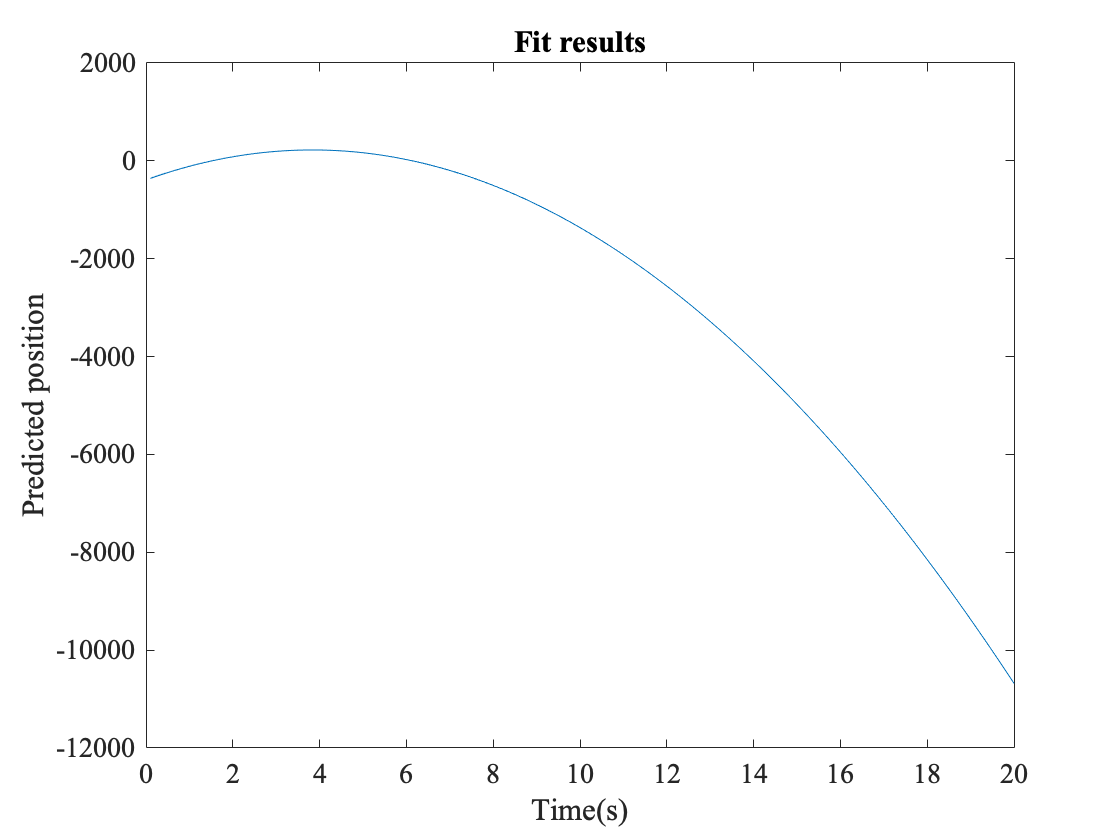

yfit=modelfun(beta,t);
figure
plot(t,yfit)
title('Fit results')
xlabel('Time(s)');ylabel('Predicted position')

In sum, to fit an arbitrary data model function of 1 independent variable and any number of unknown parameters to data with `nlinfit`, define a handle to an anonymous model function (using @) using components of a vector of parameters and a vector of independent variable sample values passed as arguments. The function must calculate (using vectorized math) and returns a vector of predicted values. Create another vector of initial values for the parameters. Create a vector containing the independent variable values. Set fitting options as desired including weights if desired. Call nlinfit with these inputs and catch all the outputs starting with the best estimates for the parameters in the order shown above. Use the outputs to compute the covariance matrix, and compute  the standard errors from the covariance matrix.

This sounds complicated but is just about 6 lines of code to do something quite impossible for a human. This fits an arbitrary function to an arbitrary amount of data essentially. Thanks MATLAB.

#### Nonlinear regression with `fitnlm`

The MATLAB nonlinear regression function called [fitnlm ](https://www.mathworks.com/help/stats/fitnlm.html)requires the same input data and input model function definition as `nlinfit`. It returns and we catch a fit results object we call `mdl` which, if allowed to print itself, lists the parameters, the estimated values, the standard errors, and two values `tState` and `pValue` describing the statistical significance of the result, along with statistics  $R^2$ and $F$. (We will not go into the interpretation of these statistics here.) Note: we are reusing the modelfun and b0 defined above so if you have switched to 4 parameters, that will apply here too.

Call `fitnlm` with the same inputs as `nlinfit` and catch the results. Do not include a semicolon in order to see the results.

mdl = fitnlm(t,y,modelfun,b0)

mdl = Nonlinear regression model:
    y ~ (b1 + b2*t + b3*t*t/2)

Estimated Coefficients:
          Estimate      SE       tStat       pValue  
          ________    ______    _______    __________

    b1    -388.98      60.97      -6.38    1.2379e-09
    b2     319.43     14.006     22.807     3.549e-57
    b3    -83.389     1.3498    -61.779    6.632e-131


Number of observations: 200, Error degrees of freedom: 197
Root Mean Squared Error: 285
R-Squared: 0.992,  Adjusted R-Squared 0.992
F-statistic vs. zero model: 1.5e+04, p-value = 3.02e-232

The parameter values and errors must be accessed by invoking the "methods" of the object using thing.category.name style notation. See [https://www.mathworks.com/matlabcentral/answers/234468-how-do-i-print-save-parameters-from-fitnlm](https://www.mathworks.com/matlabcentral/answers/234468-how-do-i-print-save-parameters-from-fitnlm) . 

List the parameter values in the model object returned by `fitnlm`.

beta = mdl.Coefficients.Estimate 

beta =       -388.98
       319.43
      -83.389


List the standard uncertainties (standard errors) returned by `fitnlm`.

betaErr = mdl.Coefficients.SE

betaErr =         60.97
       14.006
       1.3498


The use of fitnlm entails the same setup steps as the use of nlinfit but access to the parameter errors is more straight forward.

#### Linear regression with `polyfit`

`Polyfit` is a linear least squares fitting method you will find available as a standard quick fit option in plot window menus. As a plot window function, it does not divulge the uncertainties on the parameters, just the best estimate parameters values, and without the uncertainties, those values cannot be interpreted. To obtain the uncertainties, you have to call `polyfit` from the command line or in a script.  

To use `polyfit`, we send it the independent and dependent variable values `t` and `y` and the degree of the polynomial in the polynomial data model (with a constant counting as 0 degree). `polyfit`  returns a vector of parameter values that we catch as `parm` and a [structure](https://www.mathworks.com/help/matlab/ref/struct.html) containing additional information we catch as `S`. (We catch with a new variable name `parm` (not the usual variable name `p`) since we use the variable `p` to denote the number of parameters throughout this script.) The values in `parm` are the coefficients in the expression y= p(1)t^n+p(2)t^{n-1}+...+p(n) which is arguably a rather unfortunate definition, unfortunate because the meaning of all entries changes if you change the degree of the polynomial. So p(1) in our example is g/2 and negative. 

Let's try it.

Note: To fit to a cubic polynomial, we change 2 to 3 in the polyfit function call when jerk is enabled.

[parm,S] = polyfit(t,y,2);
if p==4
    [parm,S] = polyfit(t,y,3)
end

Print the parameter values and the structure. 

**Try this**: You can also explore these quantities via the workspace pane.

parm,S

parm =       -41.694       319.43      -388.98


S = struct with fields:
        R: [3×3 double]
       df: 197
    normr: 3993.8


The structure `S` contains a matrix `R`, the number of degrees of freedom `df`, and the `norm` of the residuals vector defined as the square root of the sum of the squares of the residuals, ie $\sqrt{\chi^2}\sigma$. To access elements of a structure like S, we use `S.thing_we_want `notation to refer to `thing_we_want`.

According to the documentation for `polyfit`, given the usual simplistic assumptions about the error model, an estimate of the covariance matrix of `p `is`(Rinv*Rinv')*normr^2/df`, where `Rinv` is the inverse of `R`. 

Compute the covariance matrix from elements of the structure returned by polyfit.

Rinv = inv(S.R);
CovPolyfit= (Rinv*Rinv')*S.normr^2/S.df

CovPolyfit =       0.45549      -9.1553       30.823
      -9.1553       196.17       -741.6
       30.823       -741.6       3717.3


Extract the diagonal elements as the parameter variances and take the square roots to get their standard deviations.

ErrPolyfit = sqrt(diag(CovPolyfit))

ErrPolyfit =        0.6749
       14.006
        60.97


You can compare these Polyfit results to previous results, noting we are fitting for a p(1)=g/2, not for g.

FYI: If the errors in the data in `y` are independent and normal with constant variance, then `[y,delta] = polyval(...)` produces error bounds that contain at least 50% of the predictions. That is, `y` ± `delta `contains at least 50% of the predictions of future observations at `x`.  That's a nonstandard range. Be aware.

#### Linear regression with `fit`

The [fit](https://www.mathworks.com/help/curvefit/fit.html) function offers a collection of standard functional forms including nonlinear spline-like methods designed for applications outside physics. It will perform polynomial fits if we preset that choice via a call to [fitoptions](https://www.mathworks.com/help/curvefit/fitoptions.html). 

Let's try it.

Note: To fit to a cubic, we change `'poly2'` to `'poly3'` in the following setup and in the call to` fit` .

if p==3
    options=fitoptions('poly2')
else
    options = fitoptions('poly3')
end


options =

    Normalize: 'off'
      Exclude: []
      Weights: []
       Method: 'LinearLeastSquares'
       Robust: 'Off'
        Lower: [1×0 double]
        Upper: [1×0 double]



Our toy model happens to be suceptible to a polynomial fit. We offer `fit` the times and observed positions and ask for a degree 2 polynomial fit. We catch a fit model object `f `that lists the fitted parameter values and 95% confidence bounds (ignoring off-diagonal elements of the covariance matrix). We also catch a structure `gof` which contains statistical information and another structure `output` with the jacobian and summed squared residuals from which we can construct the standard errors.

if p==3
    [f, gof, output]=fit(t',y','poly2')
else
    [f, gof, output]=fit(t',y','poly3')
end

f =      Linear model Poly2:
     f(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =      -41.69  (-43.03, -40.36)
       p2 =       319.4  (291.8, 347.1)
       p3 =        -389  (-509.2, -268.7)

gof = struct with fields:
           sse: 1.595e+07
       rsquare: 0.99247
           dfe: 197
    adjrsquare: 0.99239
          rmse: 284.54


output = struct with fields:
        numobs: 200
      numparam: 3
     residuals: [200×1 double]
      Jacobian: [200×3 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


To access the results, we have to address the elements of the returned structures. 

We can get confidence levels as follows:

level = 0.95;
ci = confint(f,level)

ci =       -43.025       291.81      -509.22
      -40.363       347.05      -268.75


#### The end